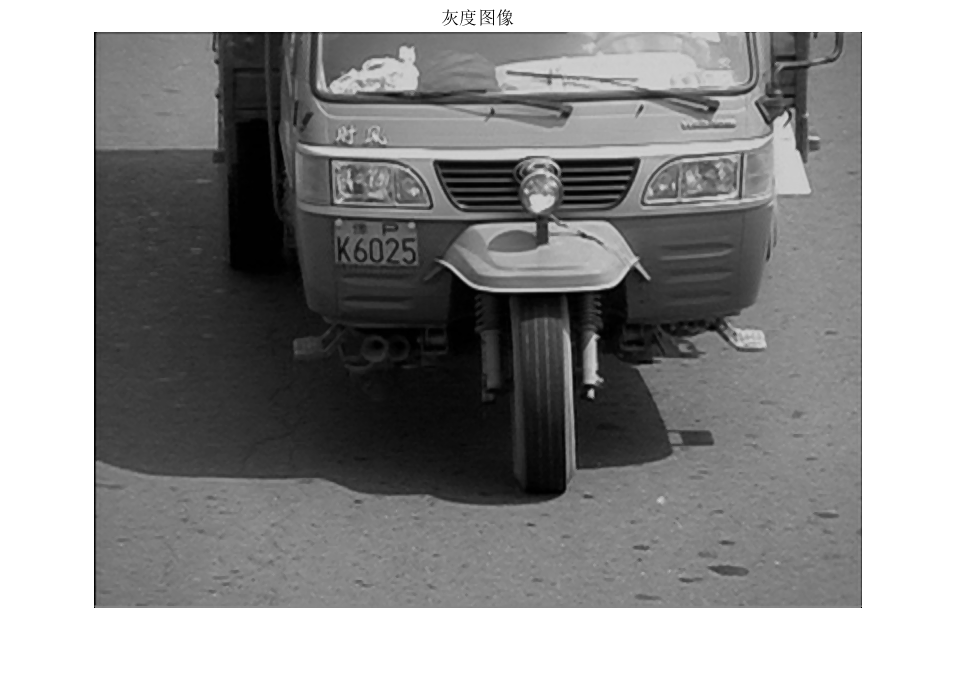

clc;clear;close all;
img = imread('images\01.jpg');
% imshow(img);title('原始图像');

img_gray = preprocess(img);
imshow(img_gray);title("灰度图像");

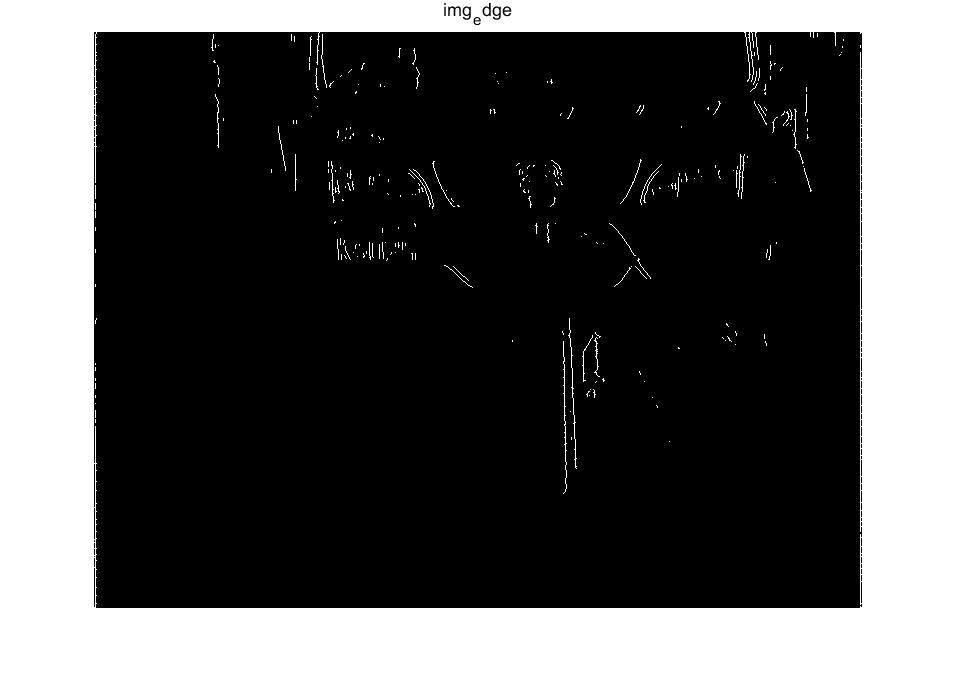


[sobel_vertical,Prewitt_vertical,Roberts_vertical,log_vertical,Canny_vertical] = edge_detect(img_gray);
img_edge = Prewitt_vertical;
imshow(img_edge);title("img_edge");

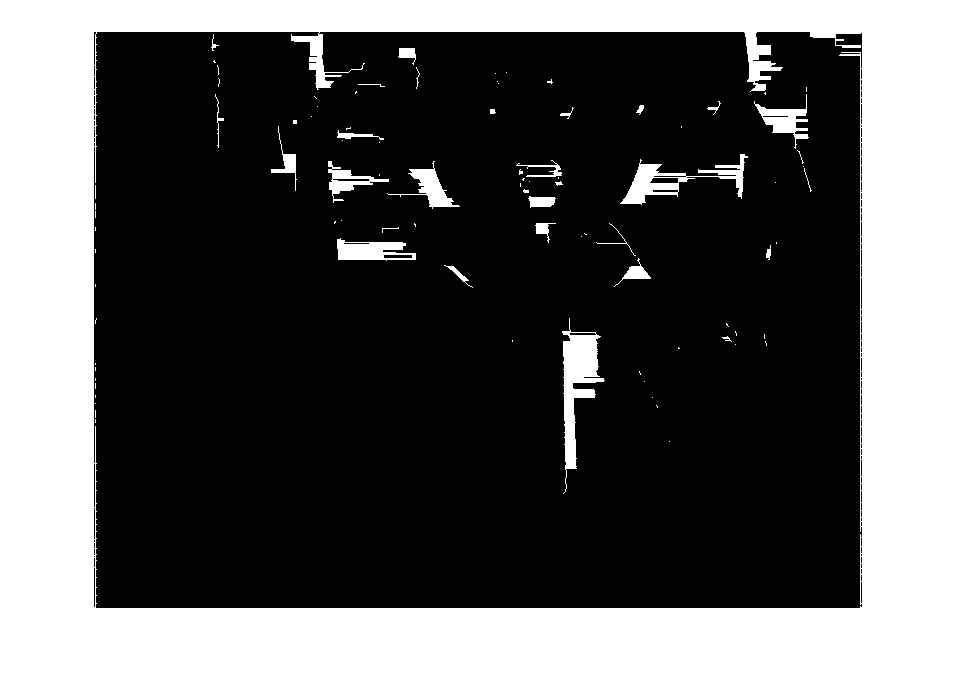

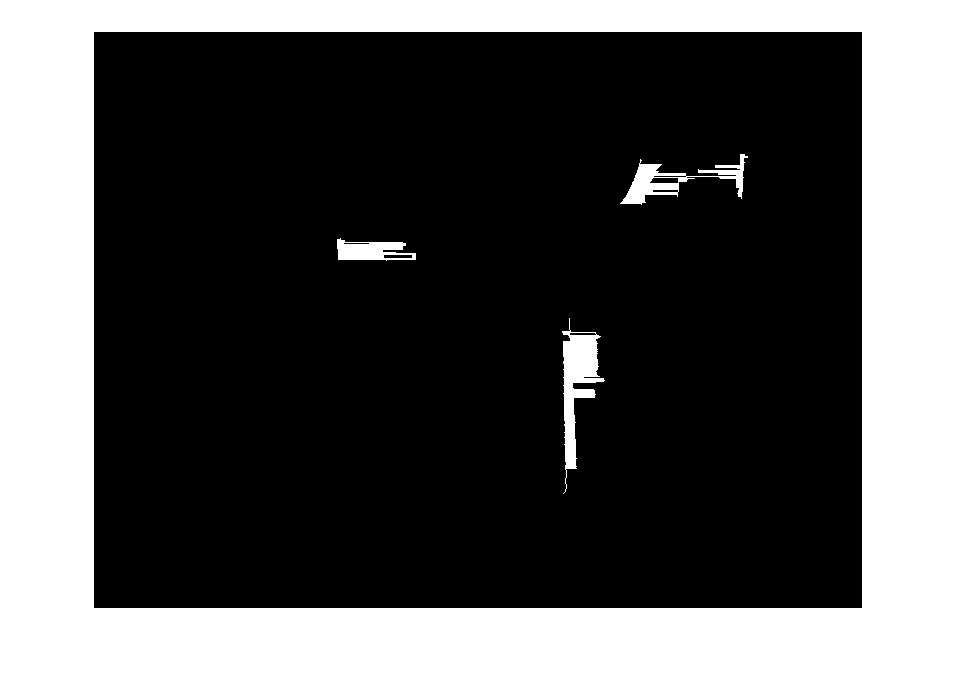

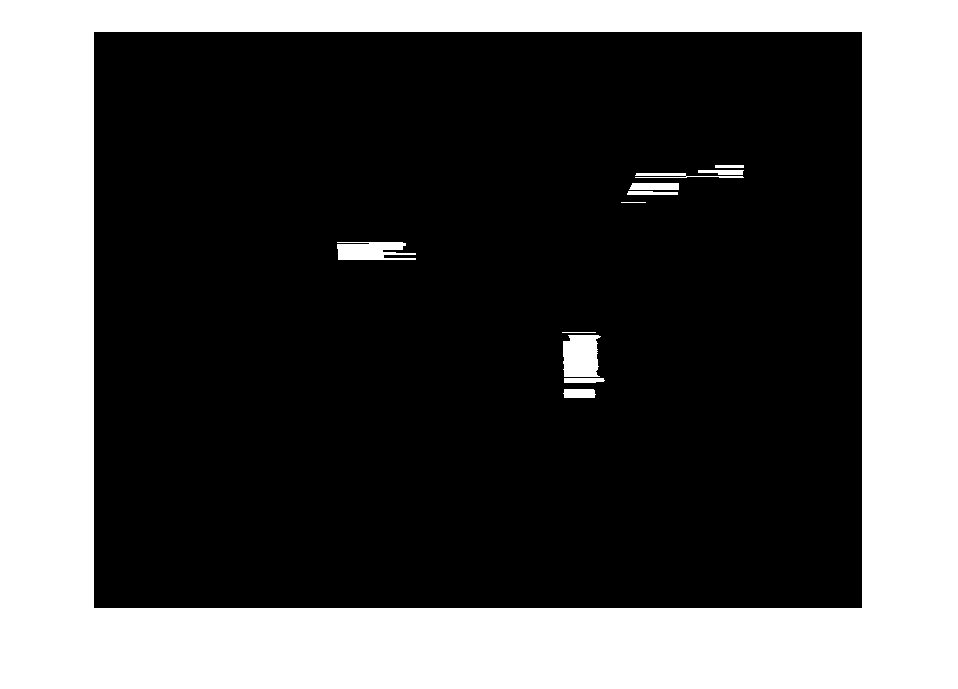


img_morphology = morphology(img_edge,1000);

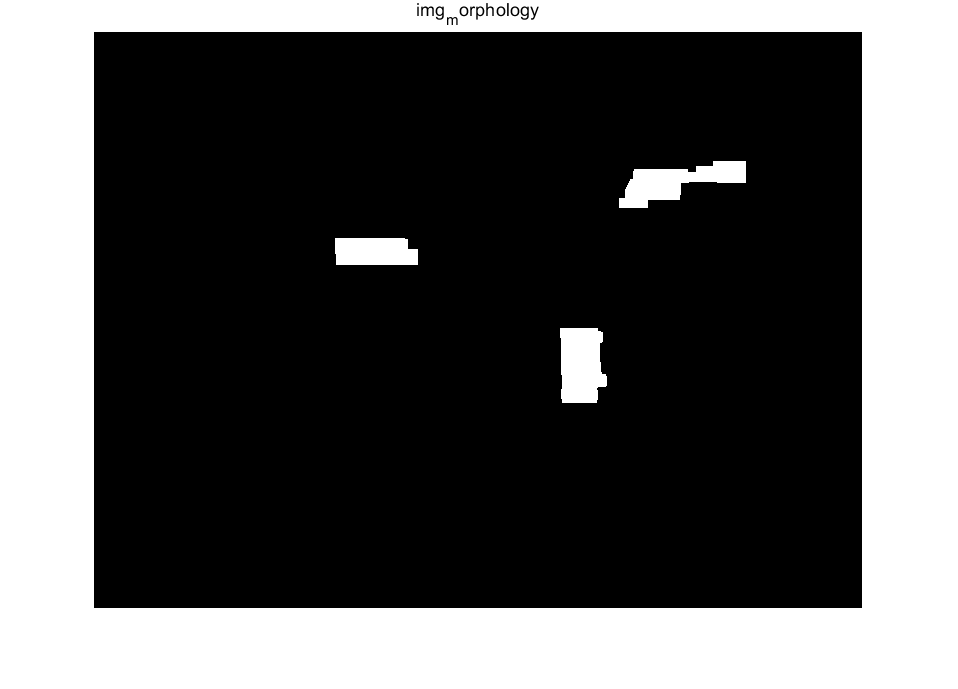

imshow(img_morphology);title("img_morphology");

function img_morphology = morphology(img,remove_threshold)
se1=strel('rectangle',[1,25]);
bw_close=imclose(img,se1);
imshow(bw_close)

bw_close = bwareaopen(bw_close,remove_threshold);  % 移除小对象
figure()
imshow(bw_close)

se2=strel('rectangle',[1,25]);
bw_open=imopen(bw_close,se2);
figure()
imshow(bw_open)

se3 = strel('rectangle',[10,5]);
img_morphology = imdilate(bw_open,se3);
end